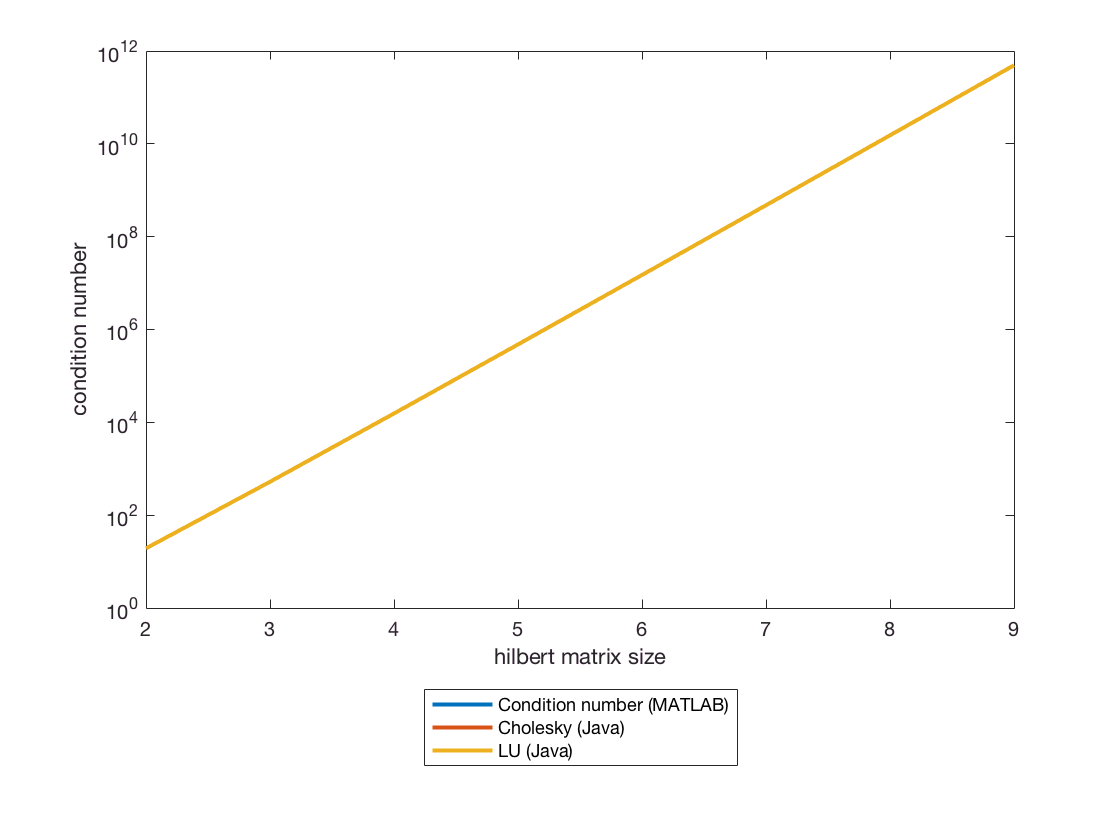

format short;

size = 9;
R=[];
for idx = 2:size
    
    H = hilb(idx);
    x = ones(idx, 1);
    
    condNr = cond(H);
    
    b = H*x;
    
    residuum = H * (x - b);
    
    normResiduum = norm(residuum, 'inf');
    
    x_hut_soll = H\b;
    
    deltaX = x_hut_soll - x;
    normDeltaX = norm(deltaX, 'inf');
    
    error = normDeltaX / (norm(x, 'inf'));
    
    A = [idx normResiduum normDeltaX condNr error];
    R = cat(1, R, A);
end

JChol = [
2	0.0						7.771561172376096E-16							19.281470067903975							1							7.771561172376096E-16
3	0.0						7.438494264988549E-15							524.0567775860604							1							7.438494264988549E-15
4	1.1102230246251565E-16						4.446443213623752E-13							15513.738738928572							2							4.446443213623752E-13
5	4.440892098500626E-16						5.374589662210383E-12							476607.2502427893							2							5.374589662210383E-12
6	2.220446049250313E-16						4.753852866912212E-10							1.4951058641184084E7							3							4.753852866912212E-10
7	2.220446049250313E-16						2.0664429167815968E-8							4.7536735663661927E8							3							2.0664429167815968E-8
8	2.220446049250313E-16						4.589680020483655E-7							1.5257576153179848E10							4							4.589680020483655E-7
9	2.220446049250313E-16						1.7953464824249643E-5							4.931534842691804E11							4							1.7953464824249643E-5    
];
JLU = [
2	0.0						6.661338147750939E-16							19.281470067903975							1							6.661338147750939E-16
3	0.0						9.992007221626409E-15							524.0567775860604							1							9.992007221626409E-15
4	1.1102230246251565E-16						6.113998196610737E-13							15513.738738928572							2							6.113998196610737E-13
5	1.1102230246251565E-16						6.16839912481737E-13							476607.2502427893							3							6.16839912481737E-13
6	2.220446049250313E-16						5.260377688998119E-10							1.4951058641184084E7							3							5.260377688998119E-10
7	0.0						2.5658763447289346E-8							4.7536735663661927E8							3							2.5658763447289346E-8
8	2.220446049250313E-16						4.188288138529117E-7							1.5257576153179848E10							4							4.188288138529117E-7
9	2.220446049250313E-16						1.9578086971283604E-5							4.931534842691804E11							4							1.9578086971283604E-5    
];

g = GraphLogScale;
g.x = R(:,1);

g.y = R(:,4);
g.y1 = JChol(:,4);
g.y2 = JLU(:,4);
g.log_plot_Y('Condition number (MATLAB)', 'hilbert matrix size', 'condition number')

ans =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [2 3 4 5 6 7 8 9]
              YData: [19.2815 524.0568 1.5514e+04 4.7661e+05 1.4951e+07 4.7537e+08 1.5258e+10 4.9315e+11]
              ZData: [1x0 double]

  Show all properties


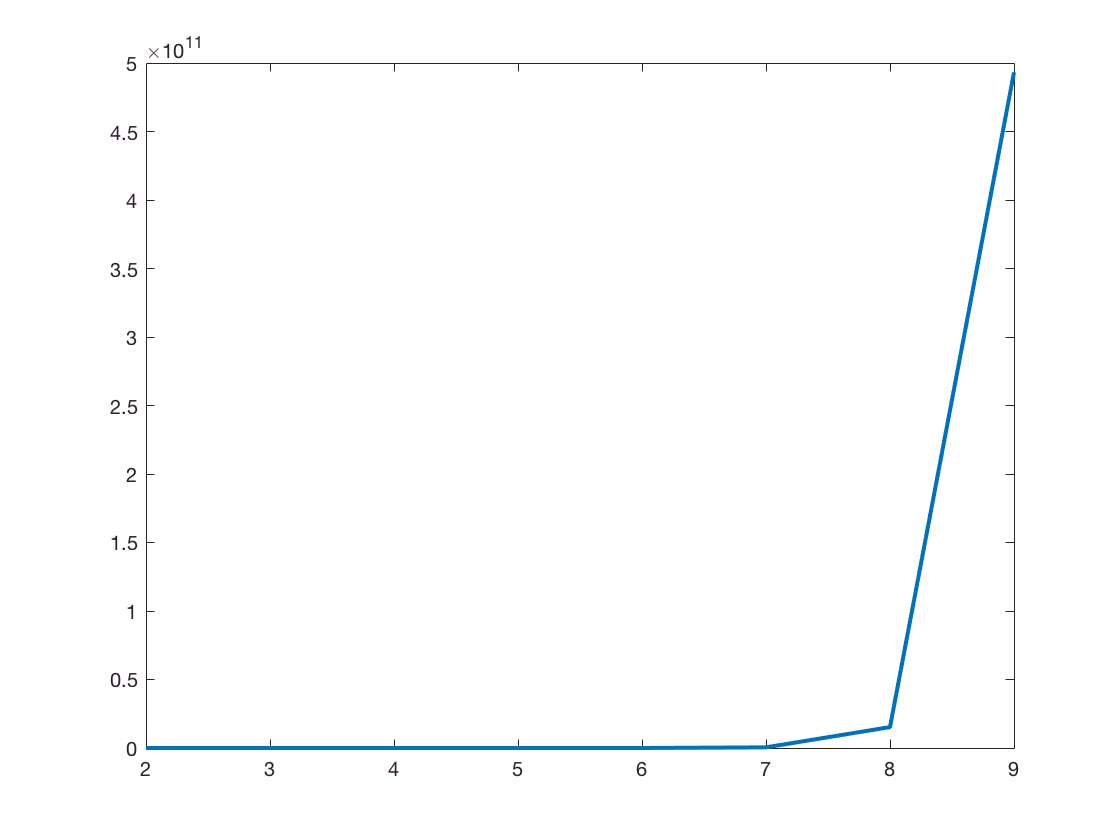

g.f_plot

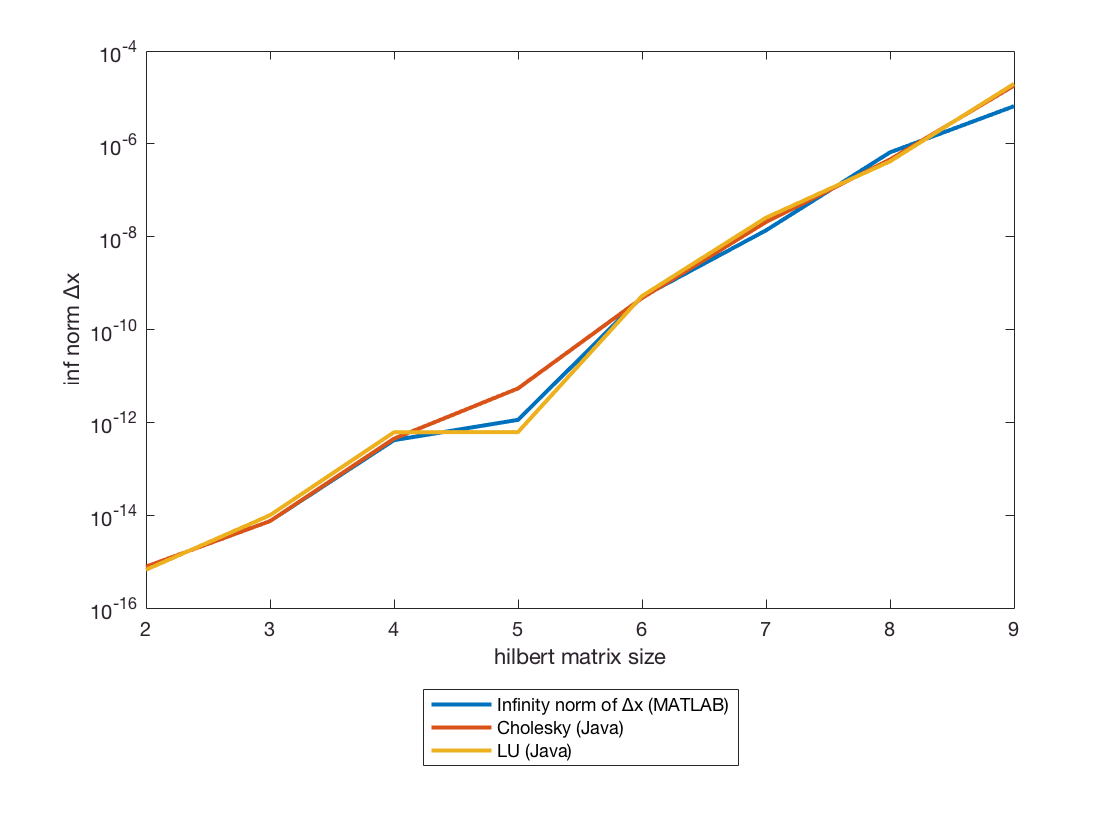


g.y = R(:,3);
g.y1 = JChol(:,3);
g.y2 = JLU(:,3);
g.log_plot_Y('Infinity norm of ∆x (MATLAB)', 'hilbert matrix size', 'inf norm ∆x')

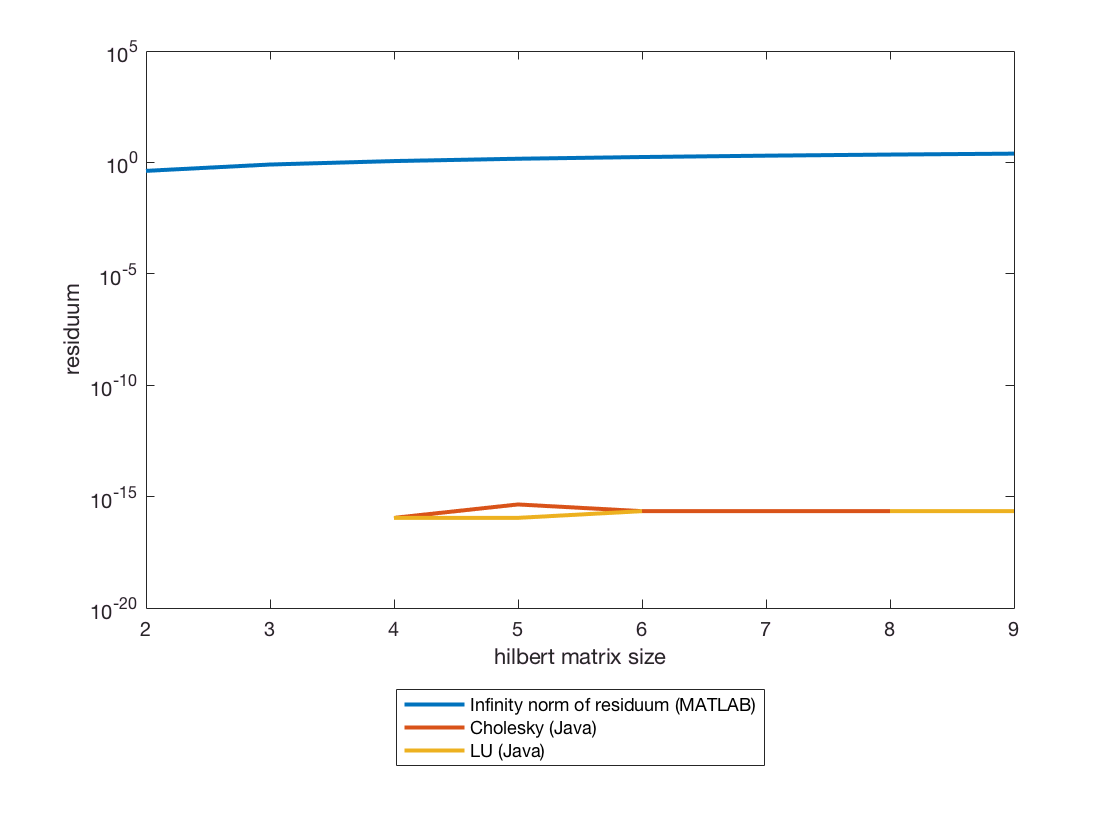


g.y = R(:,2);
g.y1 = JChol(:,2);
g.y2 = JLU(:,2);
g.log_plot_Y('Infinity norm of residuum (MATLAB)', 'hilbert matrix size', 'residuum')

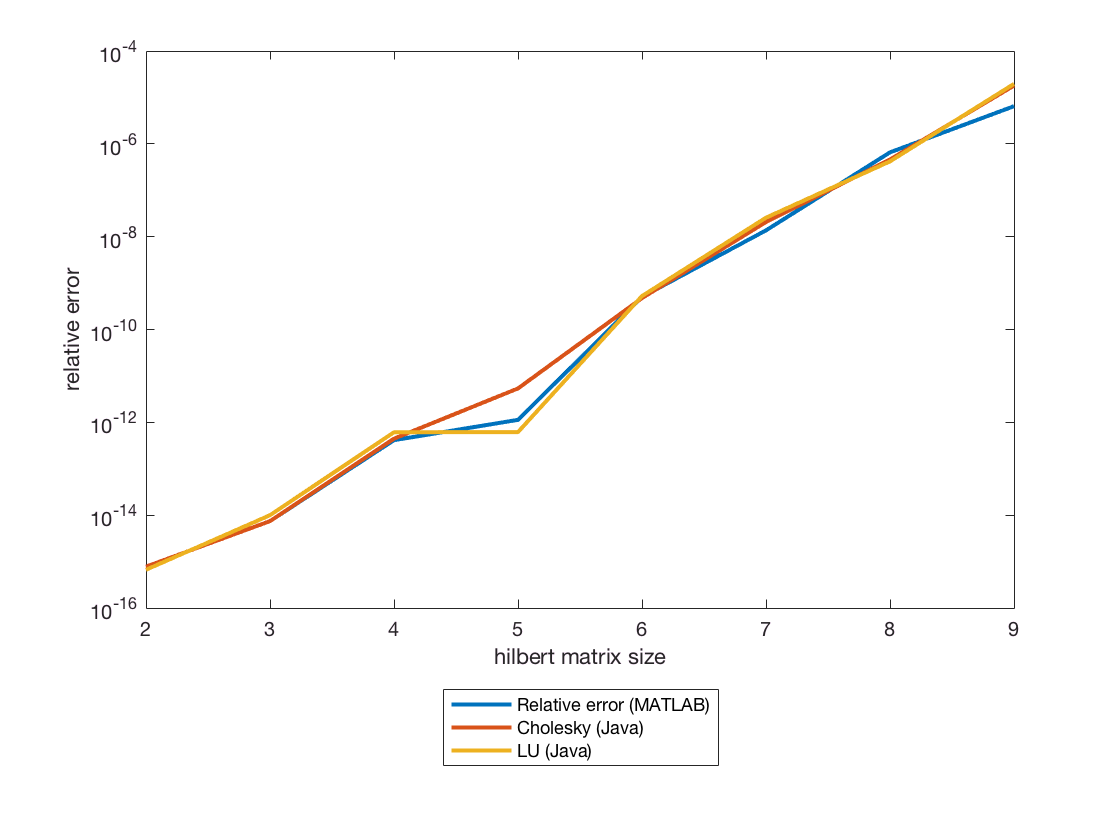


g.y = R(:,5);
g.y1 = JChol(:,6);
g.y2 = JLU(:,6);
g.log_plot_Y('Relative error (MATLAB)', 'hilbert matrix size', 'relative error')

ans =   Scatter (ammount of ones in result vektor (Java)) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [2 3 4 5 6 7 8 9]
              YData: [1 1 2 2 3 3 4 4]
              ZData: [1x0 double]
              CData: [0 0.4470 0.7410]

  Show all properties


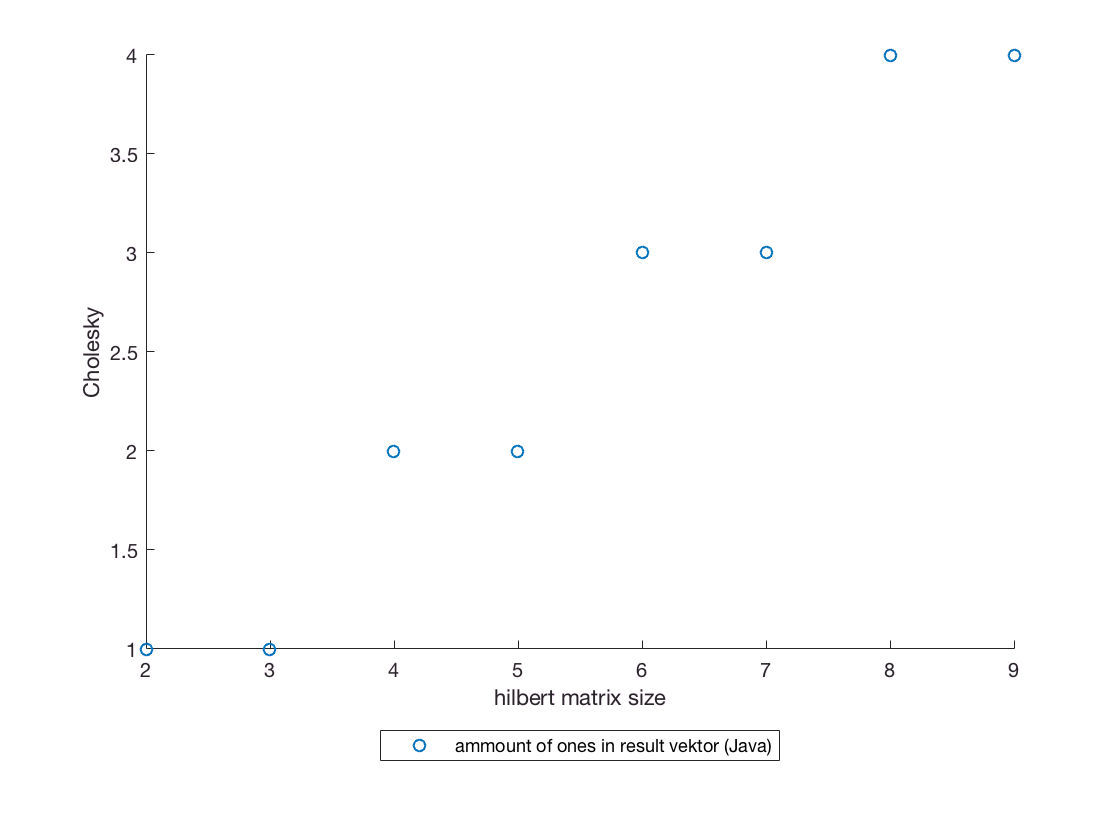


g.y = JChol(:,5);
g.scater_plot('Java Cholesky Impl', 'hilbert matrix size', 'ammount of ones in result vektor')

ans =   Scatter (ammount of ones in result vektor (Java)) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [2 3 4 5 6 7 8 9]
              YData: [1 1 2 3 3 3 4 4]
              ZData: [1x0 double]
              CData: [0 0.4470 0.7410]

  Show all properties


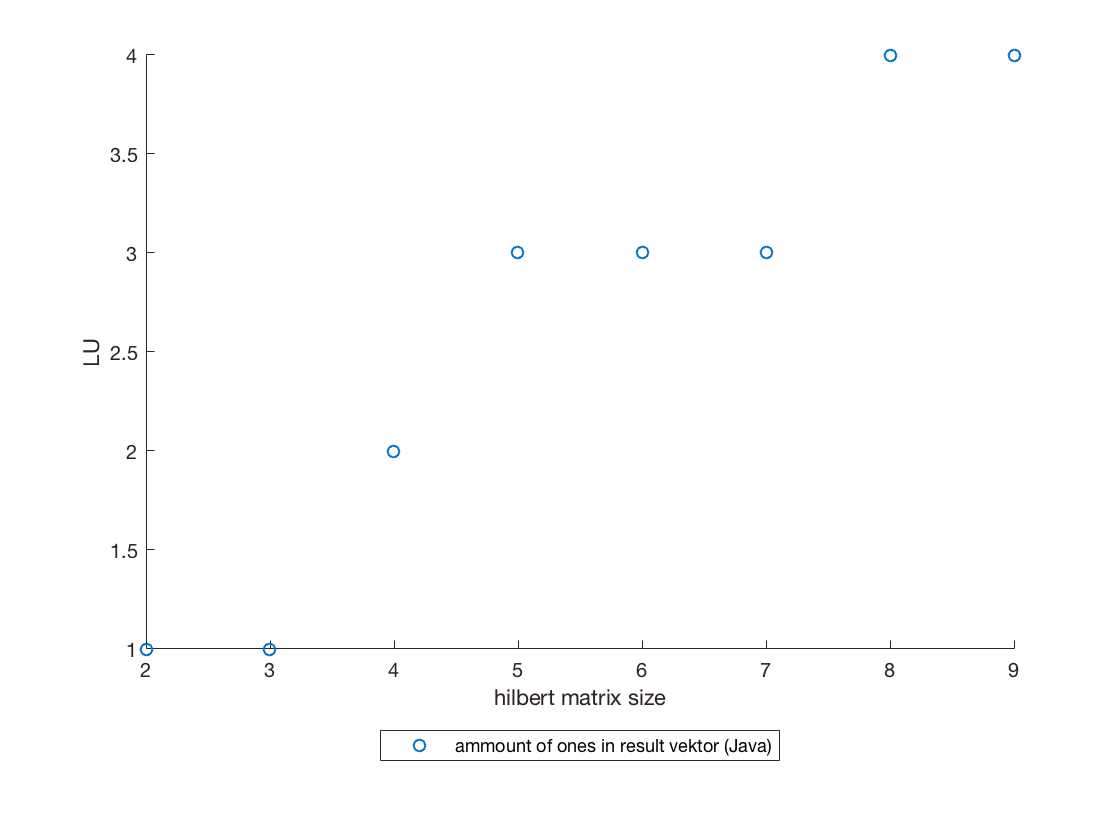


g.y = JLU(:,5);
g.scater_plot('Java LU Impl', 'hilbert matrix size', 'ammount of ones in result vektor')